# EE 451 Homework 9

# Lisa Jacklin

# 11/11/2023

%problem 1: Design a high pass filter. We need to determine the impulse
%response given that it is causal and FIR
% note that we want a cutoff wc = pi/2 via the windowing method

%part a: use rectangular window

%part b: using hamming window


%problem 2: design a band pass filter
%determine the impulse response of a causal, nonrecursive (FIR) filter to
%be used to process analog data sampled at fs = 1000hz.
%include the specifications where the passband is between 200 and 250hz,
%and frequency resolution is 20hz.

Fs = 1000;
Fr = 20;
start_frequency = 200;      % Start frequency in Hz
end_frequency = 250;        % End frequency in Hz

f = 0:1:Fs;

%now, to built the length of the signal
%and make sure it is 1 when we expect it to be
Hf = zeros(size(f));

% Set values in the passband to 1
for i = 1:length(f)
    if (start_frequency <= i * Fs / length(f)) && (i * Fs / length(f) <= end_frequency)
        Hf(i) = 1;
    end
end

%part a: sketch |H(f)|
% Plot the signal
stem(Hf);
title('Problem 1a: Sketch of |H(f)|');
xlabel('Frequency (Hz)');
ylabel('Amplitude');% Set values in the passband to 1

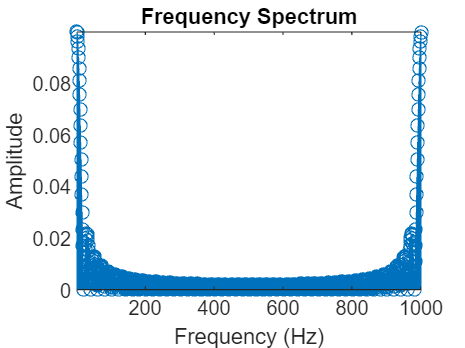


%Part b: graph |H(w)|
% Plot the spectrum |H(w)|
stem( abs(fft(Hf))/length(Hf)*2);
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0, Fs/2]);

% Adjust the axis for better visibility
axis tight;

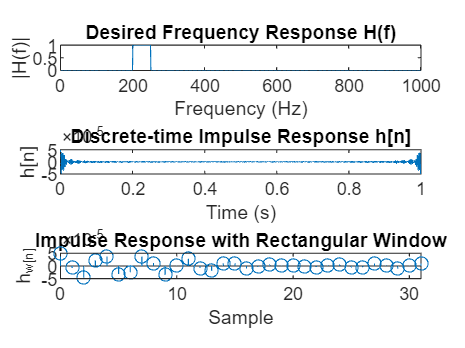


%part c
% Inverse Fourier Transform to get continuous-time impulse response h(t)
ht = ifft(ifftshift(Hf));

% Discretization to obtain discrete-time impulse response hn
Fs = 1000; % Sampling rate
Ts = 1 / Fs; % Sampling period
t_discrete = 0:Ts:(length(ht) - 1) * Ts;
hn = ht * Ts; % Discretization

% Apply rectangular window to hn
window_size = 32; % Adjust the window size as needed
rectangular_window = ones(1, window_size);
hw_n = hn(1:window_size) .* rectangular_window;

% Plot the results
figure;

subplot(3, 1, 1);
plot( abs(Hf));
title('Desired Frequency Response H(f)');
xlabel('Frequency (Hz)');
ylabel('|H(f)|');

subplot(3, 1, 2);
plot(t_discrete, hn);
title('Discrete-time Impulse Response h[n]');
xlabel('Time (s)');
ylabel('h[n]');

subplot(3, 1, 3);
stem(0:window_size-1, hw_n);
title('Impulse Response with Rectangular Window');
xlabel('Sample');
ylabel('h_w[n]');

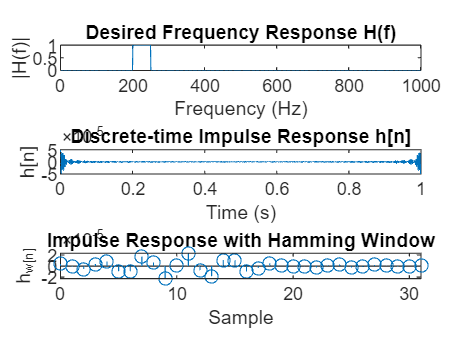

%part d: h(n) using ham filtering
% Discretization to obtain discrete-time impulse response hn
Ts = 1 / Fs; % Sampling period
t_discrete = 0:Ts:(length(ht) - 1) * Ts;
hn2 = ht * Ts; % Discretization

% Apply Hamming window to hn
window_size = 32; % Adjust the window size as needed
hamming_window = hamming(window_size)';
hw_n = hn2(1:window_size) .* hamming_window;

% Plot the results
figure;

subplot(3, 1, 1);
plot( abs(Hf));
title('Desired Frequency Response H(f)');
xlabel('Frequency (Hz)');
ylabel('|H(f)|');

subplot(3, 1, 2);
plot(t_discrete, hn2);
title('Discrete-time Impulse Response h[n]');
xlabel('Time (s)');
ylabel('h[n]');

subplot(3, 1, 3);
stem(0:window_size-1, hw_n);
title('Impulse Response with Hamming Window');
xlabel('Sample');
ylabel('h_w[n]');

%part e: plot the frequency response (Hz) of the filters designed in c and
%d.


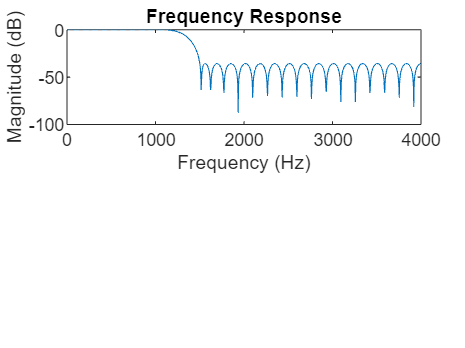


%Problem 3: Design a Low Pass Filter. Determine the impulse response of a
%causal, nonrecursive(FIR) filter with the following specifications. Use
%optimum equirriple frequency sampling method.

% Filter design parameters
PBF = 1500;     % 1.5 kHz passband frequency
Twidth = 500;   % Transition width
Astop = 50;     % Stopband attenuation in dB
Fs3 = 8000;     % Sampling frequency

%part a: determine h(n)

% Frequency response of the FIR filter
[H, Freq] = freqz(filter_coeffs, 1, 1024, Fs3);


%part b: frequency response H(w)
% Plot the frequency response
figure;
subplot(2,1,1);
plot(Freq, 20*log10(abs(H)));
title('Frequency Response');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');




%part c: compute the resultant stopband attenuation found

